n_stati = 8; n_input = 4; n_output = 4;

J_m1 = 2e-2; J_c1 = 4e-2;
J_m2 = 2e-2; J_c2 = 4e-2;
k_1 = 1000; h_1 = .02; h_m1 = .01;
k_2 = 1000; h_2 = .02; h_m2 = .01;

A = zeros(n_stati,n_stati);
A(5,:) = J_m1^-1.*[-k_1 k_1 0 0 -(h_m1+h_1) h_1 0 0];
A(6,:) = J_c1^-1.*[k_1 -k_1 0 0 h_1 -(h_1+h_m2) h_m2 0];
A(7,:) = J_m2^-1.*[0 0 -k_2 k_2 0 h_m2 -(h_m2+h_2) h_2];
A(8,:) = J_c2^-1.*[0 0 k_2 -k_2 0 0 h_2 -h_2];
A

A = 	1.0e+04 *

         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0
   -5.0000    5.0000         0         0   -0.0001    0.0001         0         0
    2.5000   -2.5000         0         0    0.0001   -0.0001    0.0000         0
         0         0   -5.0000    5.0000         0    0.0001   -0.0001    0.0001
         0         0    2.5000   -2.5000         0         0    0.0001   -0.0001


B = zeros(n_stati,n_input);
B(5,1) = J_m1^-1*1; B(6,2) = J_c1^-1*(-1); B(7,3) = J_m2^-1*1; B(8,4) = J_c2^-1*(-1);
B

B =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
    50     0     0     0
     0   -25     0     0
     0     0    50     0
     0     0     0   -25


C = zeros(n_output,n_stati);
C(1,2) = 1; C(2,4) = 1; C(3,6) = 1; C(4,8) = 1;
C

C =      0     1     0     0     0     0     0     0
     0     0     0     1     0     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     0     1


D = zeros(n_output,n_input);
D

D =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


states = {'pos_m1' 'pos_c1' 'pos_m2' 'pos_c2' ...
          'vel_m1' 'vel_c1' 'vel_m2' 'vel_c2'};
inputs = {'tau_m1' 'tau_c1' 'tau_m2' 'tau_c2'};
outputs = {'pos_c1' 'pos_c2' 'vel_c1' 'vel_c2'};

sys_ss = ss(A,B,C,D,'statename',states,'inputname',inputs,'outputname',outputs);

sys_tf = tf(sys_ss);

sys_tf =
 
  From input "tau_m1" to output...
   pos_c1:  0
 
   pos_c2:  0
 
                        25 s^2 + 50 s + 6.25
   vel_c1:  --------------------------------------------
            s^4 + 4.25 s^3 + 5.25 s^2 + 1.563 s + 0.0625
 
                                6.25
   vel_c2:  --------------------------------------------
            s^4 + 4.25 s^3 + 5.25 s^2 + 1.563 s + 0.0625
 
  From input "tau_c1" to output...
   pos_c1:  0
 
   pos_c2:  0
 
                -25 s^3 - 87.5 s^2 - 81.25 s - 9.375
   vel_c1:  --------------------------------------------
            s^4 + 4.25 s^3 + 5.25 s^2 + 1.563 s + 0.0625
 
                          -6.25 s - 9.375
   vel_c2:  --------------------------------------------
            s^4 + 4.25 s^3 + 5.25 s^2 + 1.563 s + 0.0625
 
  From input "tau_m2" to output...
   pos_c1:  0
 
   pos_c2:  0
 
                      12.5 s^2 + 25 s + 9.375
   vel_c1:  --------------------------------------------
            s^4 + 4.25 s^3 + 5.25 s^2 + 1.56

tf_joint1 = minreal(zpk(sys_tf(3,1)),1e-3)

tf_joint1 =
 
  From input "tau_m1" to output "vel_c1":
           25 (s+1.866) (s+0.134)
  ----------------------------------------
  (s+2.081) (s+1.76) (s+0.3614) (s+0.0472)
 
Continuous-time zero/pole/gain model.



tf_joint2 = minreal(zpk(sys_tf(4,3)),1e-3)

tf_joint2 =
 
  From input "tau_m2" to output "vel_c2":
          25 (s+1.925) (s+0.3246)
  ----------------------------------------
  (s+2.081) (s+1.76) (s+0.3614) (s+0.0472)
 
Continuous-time zero/pole/gain model.



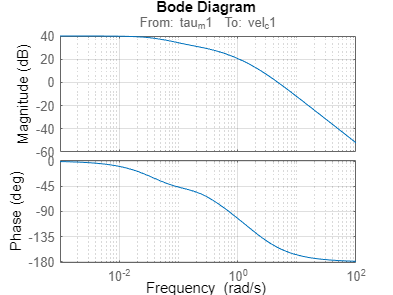


figure
bode(tf_joint1)

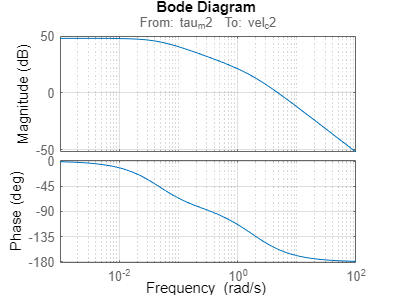


figure
bode(tf_joint2)

## Symbolic

n_stati = 8; n_input = 4; n_output = 4;

syms J_m1 J_c1 J_m2 J_c2 k_1 h_1 h_m1 k_2 h_2 h_m2 s

A = sym(zeros(n_stati,n_stati));
A(5,:) = J_m1^-1.*[-k_1 k_1 0 0 -(h_m1+h_1) h_1 0 0];
A(6,:) = J_c1^-1.*[k_1 -k_1 0 0 h_1 -(h_1+h_m2) h_m2 0];
A(7,:) = J_m2^-1.*[0 0 -k_2 k_2 0 h_m2 -(h_m2+h_2) h_2];
A(8,:) = J_c2^-1.*[0 0 k_2 -k_2 0 0 h_2 -h_2];
A

$$A = \left(\begin{array}{cccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ -\frac{k_{1}}{J_{\mathrm{m1}}} & \frac{k_{1}}{J_{\mathrm{m1}}} & 0 & 0 & -\frac{h_{1}+h_{\mathrm{m1}}}{J_{\mathrm{m1}}} & \frac{h_{1}}{J_{\mathrm{m1}}} & 0 & 0\\ \frac{k_{1}}{J_{\mathrm{c1}}} & -\frac{k_{1}}{J_{\mathrm{c1}}} & 0 & 0 & \frac{h_{1}}{J_{\mathrm{c1}}} & -\frac{h_{1}+h_{\mathrm{m2}}}{J_{\mathrm{c1}}} & \frac{h_{\mathrm{m2}}}{J_{\mathrm{c1}}} & 0\\ 0 & 0 & -\frac{k_{2}}{J_{\mathrm{m2}}} & \frac{k_{2}}{J_{\mathrm{m2}}} & 0 & \frac{h_{\mathrm{m2}}}{J_{\mathrm{m2}}} & -\frac{h_{2}+h_{\mathrm{m2}}}{J_{\mathrm{m2}}} & \frac{h_{2}}{J_{\mathrm{m2}}}\\ 0 & 0 & \frac{k_{2}}{J_{\mathrm{c2}}} & -\frac{k_{2}}{J_{\mathrm{c2}}} & 0 & 0 & \frac{h_{2}}{J_{\mathrm{c2}}} & -\frac{h_{2}}{J_{\mathrm{c2}}} \end{array}\right)$$

B = sym(zeros(n_stati,n_input));
B(5,1) = J_m1^-1*1; B(6,2) = J_c1^-1*(-1); B(7,3) = J_m2^-1*1; B(8,4) = J_c2^-1*(-1);
B

$$B = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{1}{J_{\mathrm{m1}}} & 0 & 0 & 0\\ 0 & -\frac{1}{J_{\mathrm{c1}}} & 0 & 0\\ 0 & 0 & \frac{1}{J_{\mathrm{m2}}} & 0\\ 0 & 0 & 0 & -\frac{1}{J_{\mathrm{c2}}} \end{array}\right)$$

C = sym(zeros(n_output,n_stati));
C(1,2) = 1; C(2,4) = 1; C(3,6) = 1; C(4,8) = 1;
C

$$C = \left(\begin{array}{cccccccc} 0 & 1 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 1 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

D = sym(zeros(n_output,n_input));
D

$$D = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

G = simplify(C*inv(s*sym(eye(n_stati))-A)*B+D) %#ok<MINV> 


tf_joint1_sym = G(4,1)

tf_joint1_sym = (G(4,3)

Error using sym/factor (line 67)
The value of 'vars' is invalid. Second argument must be a vector of symbolic variables.

Error using sym/sym2poly (line 30)
Not a polynomial.